
clear;

csvFolderName = "StockVibro";
clockTimeLimit = 3; % 体験時間 (s)
stopTime = clockTimeLimit;
stopTable = table(stopTime);
writetable(stopTable, csvFolderName + '\' + "stop.csv");

Stock Left

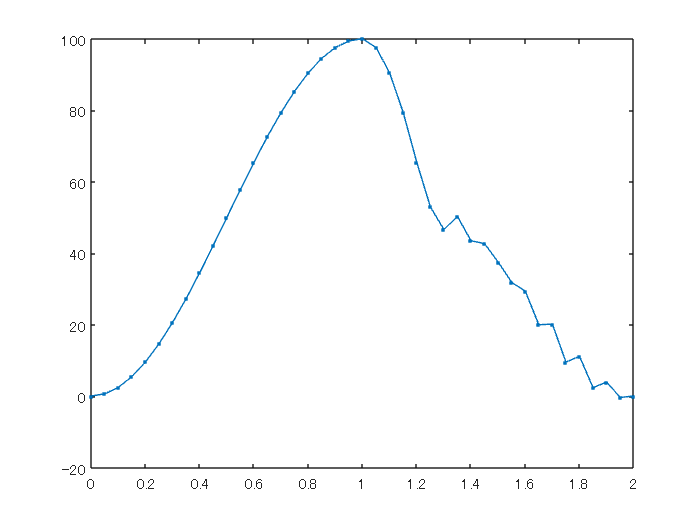

dt = 0.05;
T = 1;
xLimit = 100; % 単位 (mm)
clockTime = (0:dt:2*T)';

F = 9; % 振動周波数 Hz
Amp = 3; % 振動振幅 mm
% Amp*rand(size((0:dt:3*T/4)'));

x = [
    xLimit * (cos(pi*(0:dt:T-dt)'/T + pi) + 1)*0.5;
    xLimit * (cos((pi/2)*(0:dt:T/4-dt)'/(T/4)) + 1)*0.5;
    xLimit/2 * (cos(pi*(0:dt:3*T/4)'/(3*T/4)) + 1)*0.5 + Amp*cos(2*pi*F*(0:dt:3*T/4)');
    ];
figure;
plot(clockTime, x, '.-');

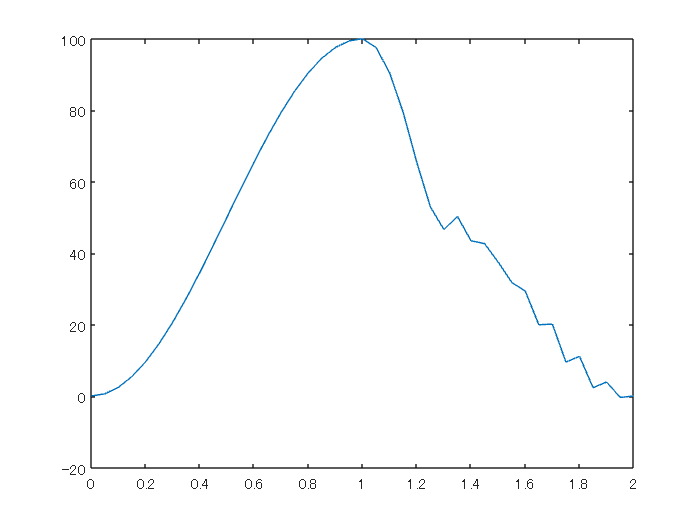


figure;
plot(clockTime, x);

StockVibroCSV = table(clockTime, x)

StockVibroCSV = 41×2 table
    clockTime       x   
    _________    _______

         0             0
      0.05       0.61558
       0.1        2.4472
      0.15        5.4497
       0.2        9.5492
      0.25        14.645
       0.3        20.611
      0.35          27.3
       0.4        34.549
      0.45        42.178
       0.5            50
      0.55        57.822
       0.6        65.451
      0.65          72.7
       0.7        79.389
      0.75        85.355


writetable(StockVibroCSV, csvFolderName + '\' + "StockVibro.csv");

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end